功能说明：Kalman滤波在船舶GPS导航定位系统中的应用

delta_t：采样间隔时间 （秒）

N：采样个数

clc;clear;
delta_t = 0.5;
N       = 80 / delta_t ;

噪声，方差决定噪声的大小

Q：由海风和海浪引起的过程噪声的方差矩阵

R：观测噪声方差

W：过程噪声

V：观测噪声

delta_w = 1e-2;
Q       = delta_w * diag([0.5 1 0.5 1]);
R       = 100 * eye(2);
W       = sqrtm(Q) * randn(4, N);
V       = sqrtm(R) * randn(2, N);

系统矩阵，本系统状态为二维

A：状态转移矩阵

B：控制矩阵

U：不考虑目标动力系统因素，假设均速直线运动，则U为0

H：观测矩阵

A       = [1 delta_t 0 0; 0 1 0 0; 0 0 1 delta_t; 0 0 0 1];
B       = [0.5 * delta_t^2 0; delta_t 0; 0 0.5 * delta_t^2; 0 delta_t];
U       = [0; 0];
H       = [1 0 0 0; 0 0 1 0];

初始化

X：目标的真实位置、速率

X(:, 1)：目标的初始位置和速率

P：协方差矩阵

Z：观测值

Z(1)：初始观测值

Xkf：Kalman估计值

err_P：误差均方值

I：二维系统

pass_time：经过的时间（秒）

X          = zeros(4, N);
X(:, 1)    = [-100 2 200 20];
P          = diag([100, 2, 100, 2]);
Z          = zeros(2, N);
Z(:, 1)    = H*X(:, 1);
Xkf        = zeros(4, N);
Xkf(:, 1)  = X(:, 1);
err_P      = zeros(N, 4);
err_P(1,1) = P(1, 1);
err_P(1,2) = P(2, 2);
err_P(1,3) = P(3, 3);
err_P(1,4) = P(4, 4);
I          = eye(4);
pass_time  = zeros(1, N);

模拟航行过程，并滤波

pass_time(1) = 0;
for k = 2: N
    pass_time(k) = pass_time(k-1) + delta_t;

第一步：航行，受状态方程的驱动

    X(:, k) = A * X(:, k-1) + W(:, k-1);

第二步：位置观测

    Z(:, k) = H * X(:, k) + V(k);

第三步：Kalman滤波

X_pre：状态预测

P_pre：协方差预测

Kg：Kalman增益

Xkf(:, k)：状态更新

P：协方差更新

    X_pre     = A * Xkf(:, k-1);
    P_pre     = A*P*A' + Q;
    Kg        = P_pre * H' * inv(H*P_pre*H' + R);
    Xkf(:, k) = X_pre + Kg * (Z(:, k) - H * X_pre);
    P         = (I-Kg*H) * P_pre;
    
    err_P(k, 1) = P(1, 1);
    err_P(k, 2) = P(2, 2);
end

计算误差

Err_Observation：滤波前的误差

Err_KalmanFilter：滤波后的误差

Err_Observation = zeros(1, N);
Err_KalmanFilter= zeros(1, N);
for k = 1: N
    Err_Observation(k) = RMS(X(:, k), Z(:, k));
    Err_KalmanFilter(k)= RMS(X(:, k), Xkf(:, k));
end

画图

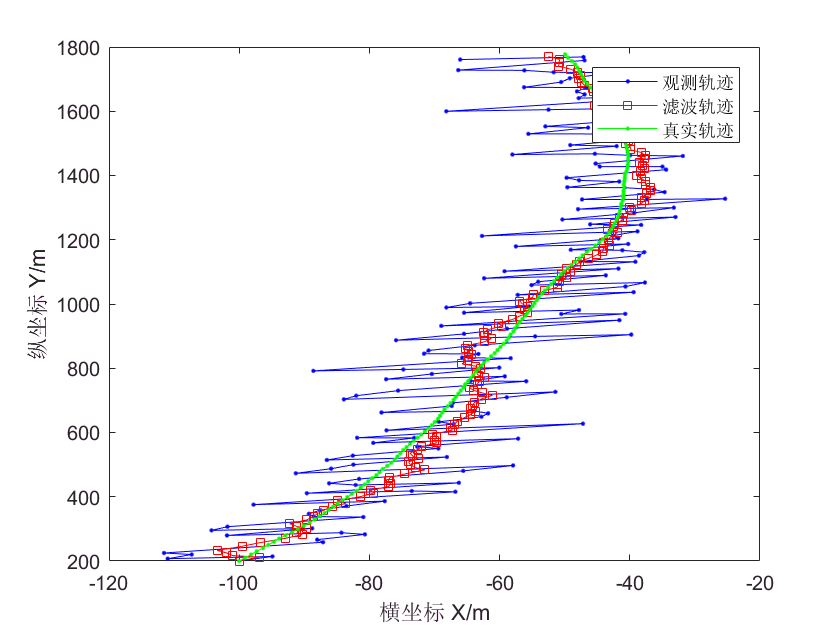

figure
hold on, box on;
plot(Z(1, :)  , Z(2, :)  , '-b.');
plot(Xkf(1, :), Xkf(3, :), '-rs');
plot(X(1, :)  , X(3, :)  , '-g.');
legend('观测轨迹','滤波轨迹','真实轨迹');
xlabel('横坐标 X/m');
ylabel('纵坐标 Y/m');

误差

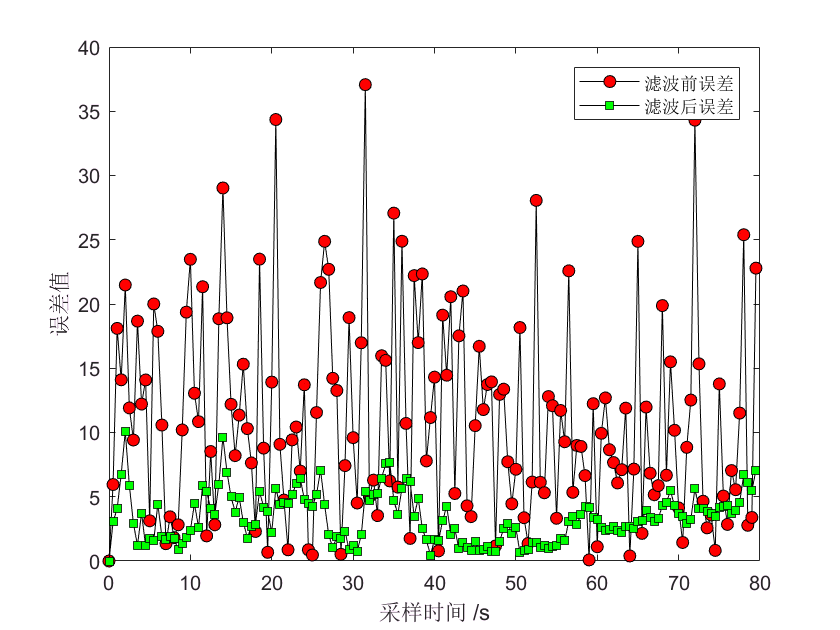

figure
figure
hold on, box on;
plot(pass_time, Err_Observation  , '-ko', 'MarkerFace', 'r');
plot(pass_time, Err_KalmanFilter , '-ks', 'MarkerFace', 'g');
legend('滤波前误差', '滤波后误差');
xlabel('采样时间 /s');
ylabel('误差值');